# Solutions for example questions

ECSE507 Optimization Final Project

Student Name : Youjin Song  / Student ID : 261067354  / Date : March 18, 2022

## Unconstrained Problems (A)~(C)

### (A) standard quadratics


$$V\left(x\right)=5+\left\lbrack 1,4,5,4,2,1\right\rbrack x+x^T \left\lbrack \begin{array}{cccccc}
9 & 1 & 7 & 5 & 4 & 7\\
1 & 11 & 4 & 2 & 7 & 5\\
7 & 4 & 13 & 5 & 0 & 7\\
5 & 2 & 5 & 17 & 1 & 9\\
4 & 7 & 0 & 1 & 21 & 15\\
7 & 5 & 7 & 9 & 15 & 27
\end{array}\right\rbrack \;;x\in R^6$$


The given problem A is standard quadratics since the 6 x 6 matrix is symmetric, positive definite matrix.

a=5;
b=[1 4 5 4 2 1]';
C=2*[9 1 7 5 4 7 ; 1 11 4 2 7 5 ;7 4 13 5 0 7;5 2 5 17 1 9 ;4 7 0 1 21 15;7 5 7 9 15 27];

if issymmetric(C) & all(eig(C))>0
    disp("This equation is standard quadratic");
end

This equation is standard quadratic


disp(["Expected Answer is :",num2str((-inv(C)*b)')])

    "Expected Answer is :"    "0.33656     0.05604    -0.43004      -0.192    …"



####     (a) steepest descent algorithm

initial=randi([-10 10],6,1);% randomly choose a 6*1 vector to start with
disp(initial')

     7     9    -8     9     3    -8



x_hat=sgd_stdquad(a,b,C,initial);

   9.0519e-05

number of total iteration: 186 
local minimum : 3.65 
location of local minimum : 0.33657    0.056053    -0.43006      -0.192    -0.27132     0.21007


####     (b) armijo step size rule selection

    For standard quadratic (like this problem), step size of j th iteration $w_j$ that minimizes value along can be determined as $\hat{w_j } =-\frac{\nabla V\left({x_j }^T s_j \right)}{{s_j }^T C{s_j } }$, by differentiation. Therefore, additional algorithm to set suitablie stepsize $\hat{w_j }$ is unnecessary. 

####     (c) Conjugate Gradient algorithm

x_hat=cg_stdquad(a,b,C,initial);

   9.5548e-05

number of total iteration: 161 
local minimum : 3.65 
location of local minimum : 0.33657    0.056052    -0.43006      -0.192    -0.27132     0.21007


####     (d) Secant algorithm

x_hat=secant_stdquad(a,b,C,initial);

   9.9215e-05

number of total iteration: 596 
local minimum : 3.65 
location of local minimum : 0.33656    0.056043    -0.43004    -0.19199    -0.27131     0.21007


### (B) $V\left(x,y\right)=-\frac{\sqrt{\left(x^2 +1\right)\left({2y}^2 +1\right)}}{x^2 +y^2 +0\ldotp 5}\;;x,y\in R$

f = @(x,y) -sqrt((x.^2+1).*(2*y.^2+1)) ./ (x.^2+y.^2+0.5);
plot_bool = true;
initial = [3,2] ; % randomly select initial point
disp(initial);

     3     2



####     (a) steepest descent algorithm

   9.0204e-05

number of total iteration: 1503 
local minimum : -2.00 
location of local minimum : 7.3959e-09    2.25e-05


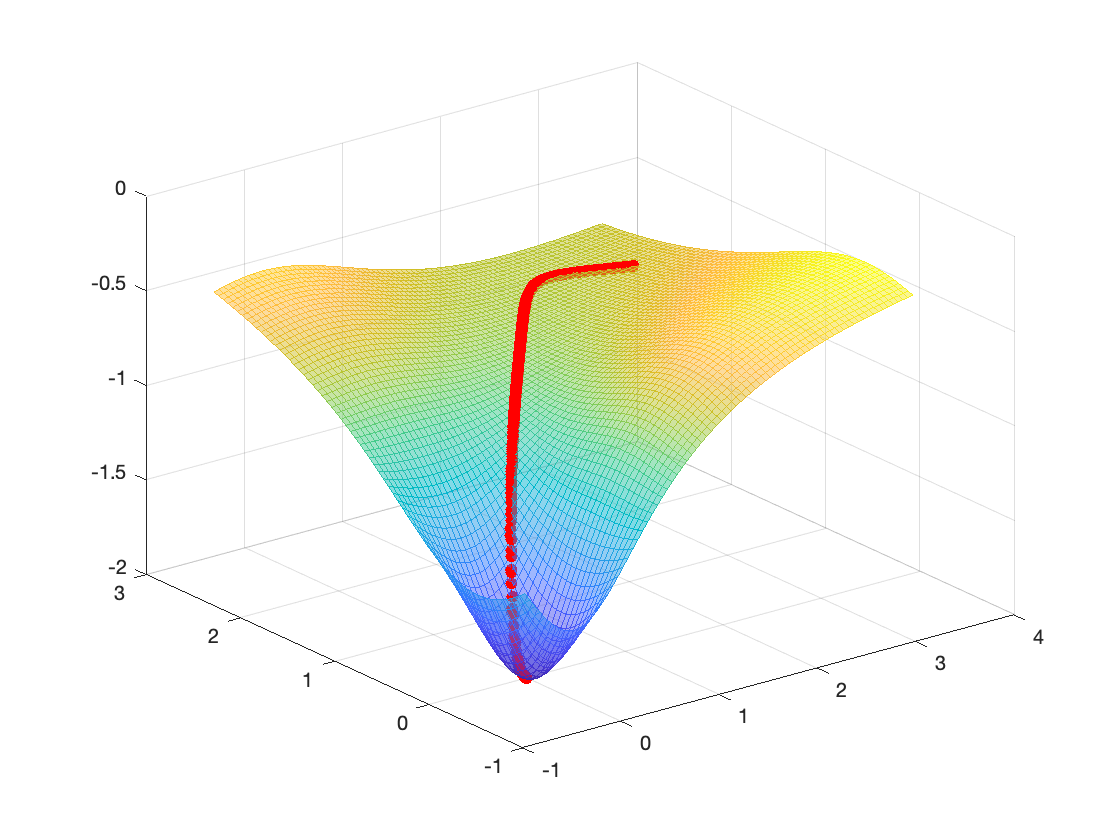

[x,xhat,fval]=sgd2d(f,initial,plot_bool);

####     (b) armijo step size rule selection

w cannot be found
number of iteration so far: 8 
current value : -2.00 
current location: -0.00046887   0.0016001


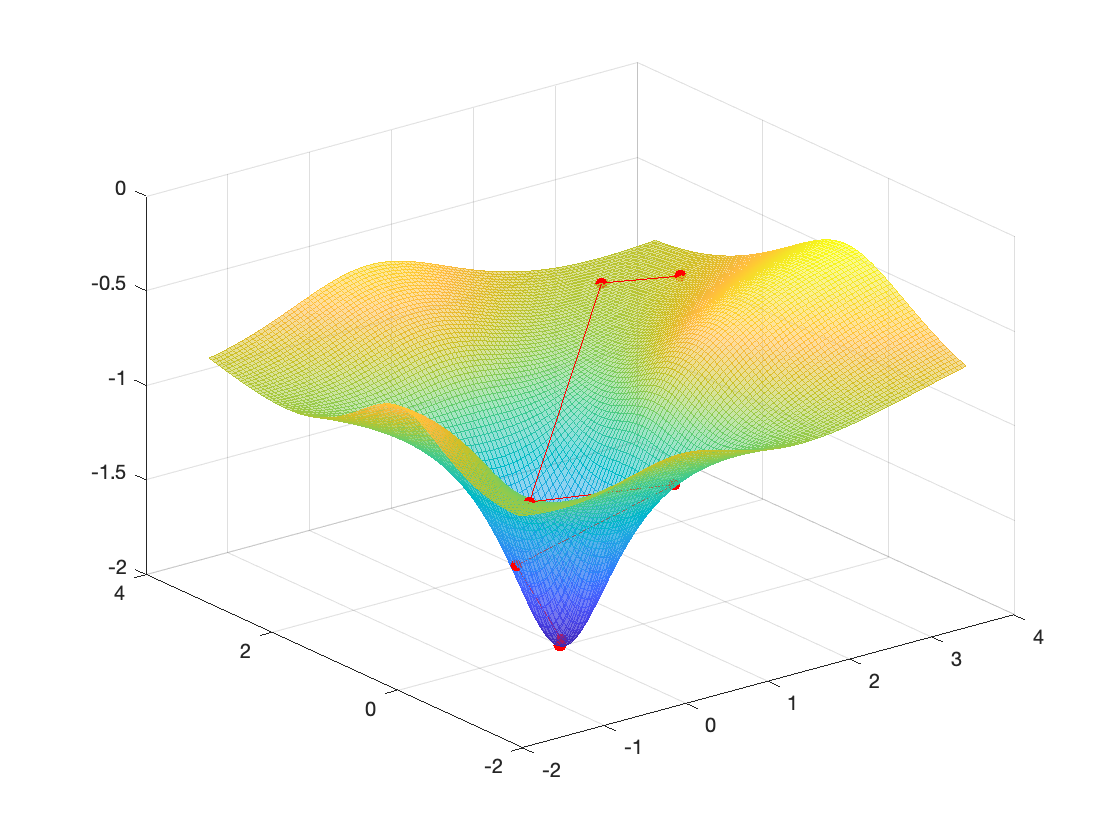

[x,xhat,fval]=sgd2d_armijo(f,initial,plot_bool);

####     (c) Conjugate Gradient algorithm

   6.3780e-05

number of total iteration: 23 
local minimum : -2.00 
location of local minimum : 9.8348e-06  5.8156e-06


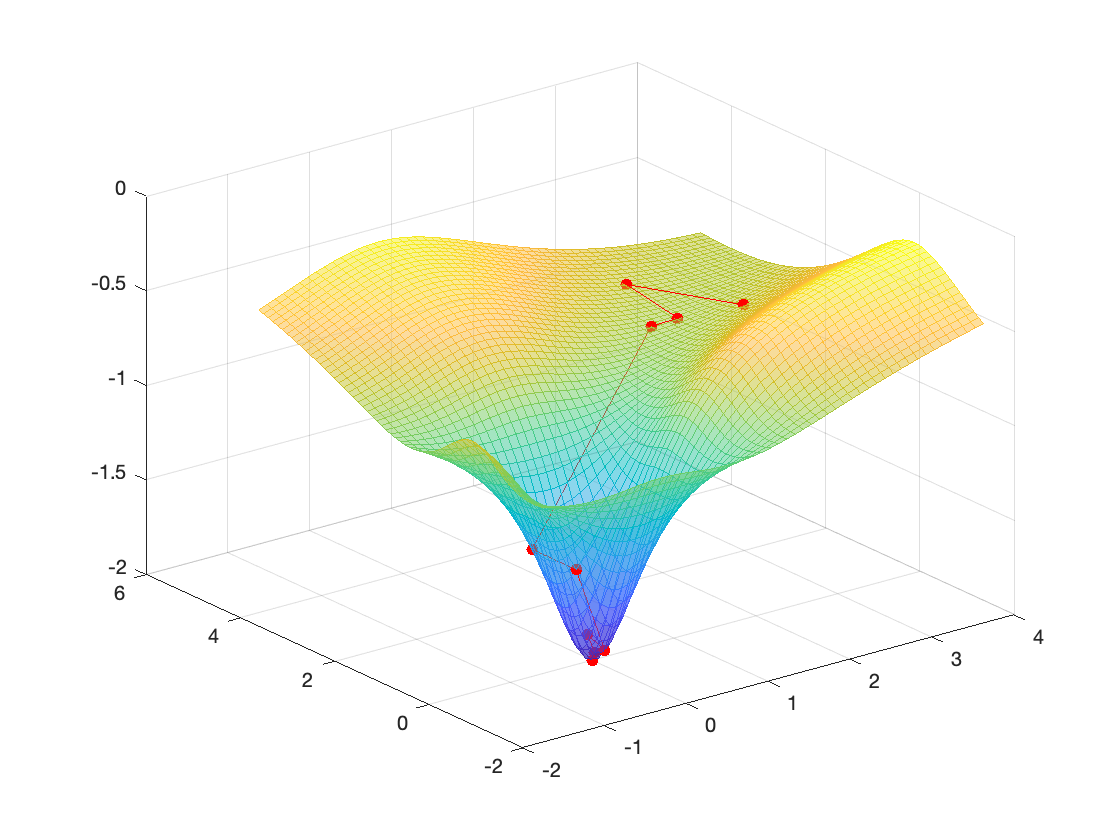

[x,xhat,fval]=cg2d(f,initial,plot_bool);

####     (d) Secant algorithm

   5.5834e-06

number of total iteration: 9 
local minimum : -2.00 
location of local minimum : 8.0686e-07  4.9665e-07


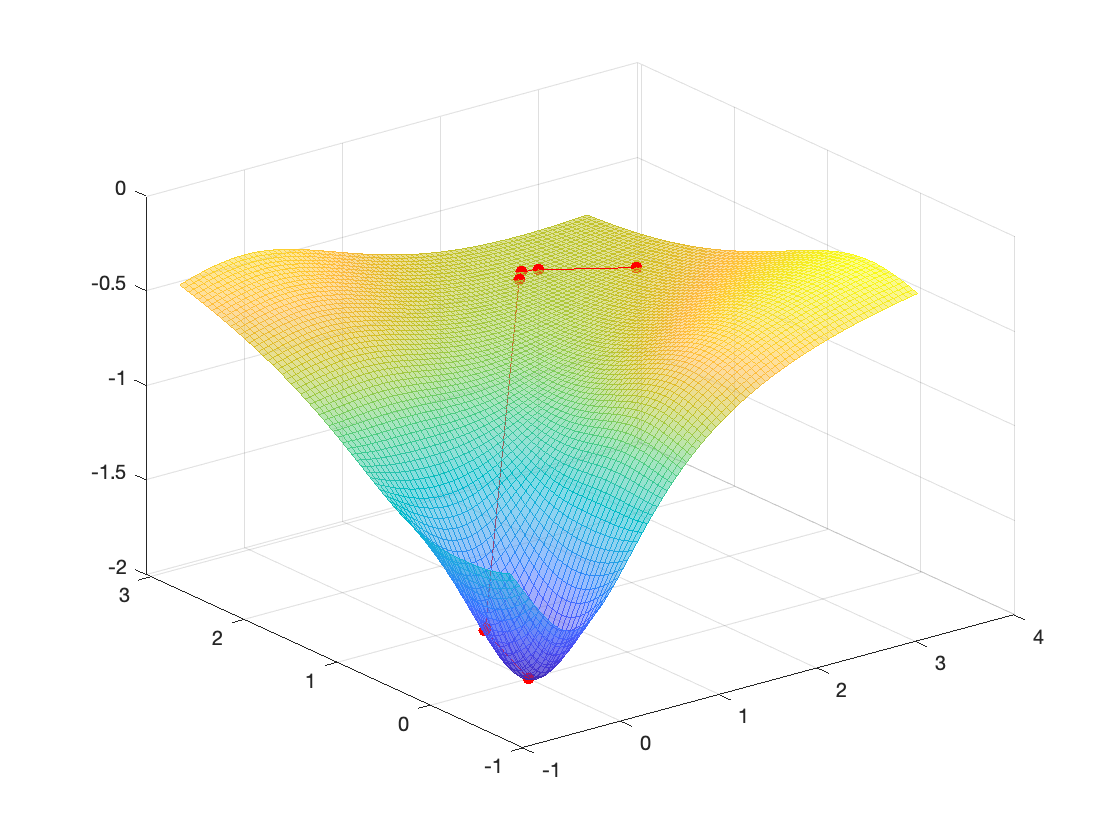

[x,xhat,fval]=secant2d(f,initial,plot_bool);

F = @(x) f(x(1),x(2));
[xhat,fval]=fminsearch(F,initial,optimset('TolX',1e-10,'MaxFunEvals',10000,'MaxIter',10000));
fprintf('local minimum by MATLAB optimization Toolbox : %.2f \n',fval);

local minimum by MATLAB optimization Toolbox : -2.00 


disp(['location of local minimum by MATLAB optimization Toolbox : ', num2str(xhat)]);

location of local minimum by MATLAB optimization Toolbox : -3.2302e-09  2.4892e-09


### (C) $V\left(x,y\right)=1+\left\lbrack \begin{array}{cc}
1 & 2
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
y
\end{array}\right\rbrack +\frac{1}{2}{\left\lbrack \begin{array}{c}
x\\
y
\end{array}\right\rbrack }^T \left\lbrack \begin{array}{cc}
12 & 3\\
3 & 10
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
y
\end{array}\right\rbrack +10\;\ln \left(1+x^4 \right)\sin \left(100x\right)+10\;\ln \left(1+y^4 \right)\cos \left(100x\right)\;;x,y\in R$

f = @(x,y) 1+x+2*y+0.5*(12*x.*x+6*x.*y+10*y.*y) + 10*log(1+x.^4).*sin(100*x) + 10*log(1+y.^4).*cos(100*y);
plot_bool = false;
initial = [1,-2] ; % randomly select initial point
disp(initial);

     1    -2



####     (a) steepest descent algorithm

[x,xhat,fval]=sgd2d(f,initial,plot_bool);

   7.3854e-05

number of total iteration: 37 
local minimum : 0.79 
location of local minimum : -0.042251    -0.16292


####     (b) armijo step size rule selection

[x,xhat,fval]=sgd2d_armijo(f,initial,plot_bool);

w cannot be found
number of iteration so far: 1014 
current value : 11372843.49 
current location: 540.75181      1233.9837


####     (c) Conjugate Gradient algorithm

[x,xhat,fval]=cg2d(f,initial,plot_bool);

minimum could not be found within maximum iteration of our algorithm


####     (d) Secant algorithm

[x,xhat,fval]=secant2d(f,initial,plot_bool);

w cannot be found
number of iteration so far: 1 
current value : 28.29 
current location: 1 -2


## Constrained Problems (1)~(3)

### (1) 1 Inequality, 1 equality constraint

minimize $V\left(x,y\right)=\left|x-1\right|+\left|y-2\right|\;;\;$$x,y\in R$

subject to : $\begin{array}{l}
h_1 \left(x,y\right)=x-y^2 \ge 0\;\\
\;h_2 \left(x,y\right)=x^2 +y^2 -1=0
\end{array}$

f0 = @(x,y) abs(x-1)+abs(y-2);
h1 = @(x,y) x - y.^2 ; %>=0
h2 = @(x,y) x.^2+y.^2-1 ; %==0
initial = [0,2];
E=1;
[x,xhat,fval]=penalty_barrier2d("penalty",f0,h1,h2,E,initial);
disp([num2str(xhat),'  fval:',num2str(fval)]);

0.70712     0.70712  fval:1.5858


Constraints are marked in dark blue, and background is a contour of objective function. A path that this algorithm searched for each iteration is marked in red. The final minimum estimation $\hat{x}$ is marked in yello diamond.

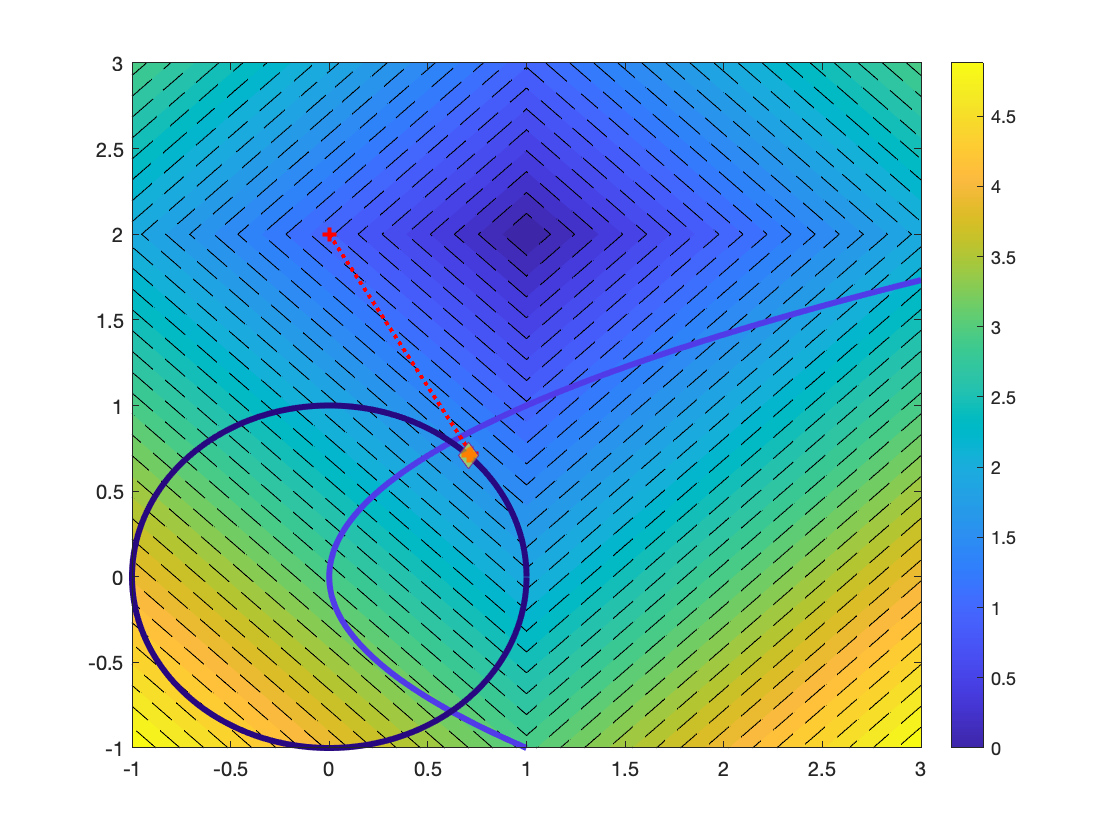

xx=-1:0.01:3;
yy=-1:0.01:3;
[X,Y]=meshgrid(xx,yy);
contourf(xx,yy,f0(X,Y),40,'--'); hold on; colorbar;
plot(yy.^2,yy,"LineWidth",3,"color",[81, 58, 232]/256);hold on;
ang=0:0.01:2*pi; plot(cos(ang),sin(ang),"LineWidth",3,"color",[40, 8, 130]/256);hold on;
plot(x(:,1),x(:,2) ,"r:","LineWidth",2,"Marker","+");hold on;
scatter(xhat(1),xhat(2),100,'d',"MarkerFaceColor","yellow","MarkerFaceAlpha",0.5); hold off;
xlim([-1,3]);ylim([-1,3]);

### (2) 2 Inequality constraints

minimize $V\left(x,y\right)=-\textrm{xy};\;$$x,y\in R$

subject to : $\begin{array}{l}
h_1 \left(x,y\right)=-x-y^2 +1\ge 0\;\\
\;h_2 \left(x,y\right)=x+y\ge 0
\end{array}$

f0 = @(x,y) -x.*y;
h1 = @(x,y) -x-y.^2 +1 ; %>=0
h2 = @(x,y) x+y; %>=0
initial = [2,-1];
E=0;
[x,xhat,fval]=penalty_barrier2d("penalty",f0,h1,h2,E,initial);
disp([num2str(xhat),'  fval:',num2str(fval)]);

0.66669     0.57736  fval:-0.38492


Constraints are marked in dark blue, and background is a contour of objective function. A path that this algorithm searched for each iteration is marked in red. The final minimum estimation $\hat{x}$ is marked in yello diamond.

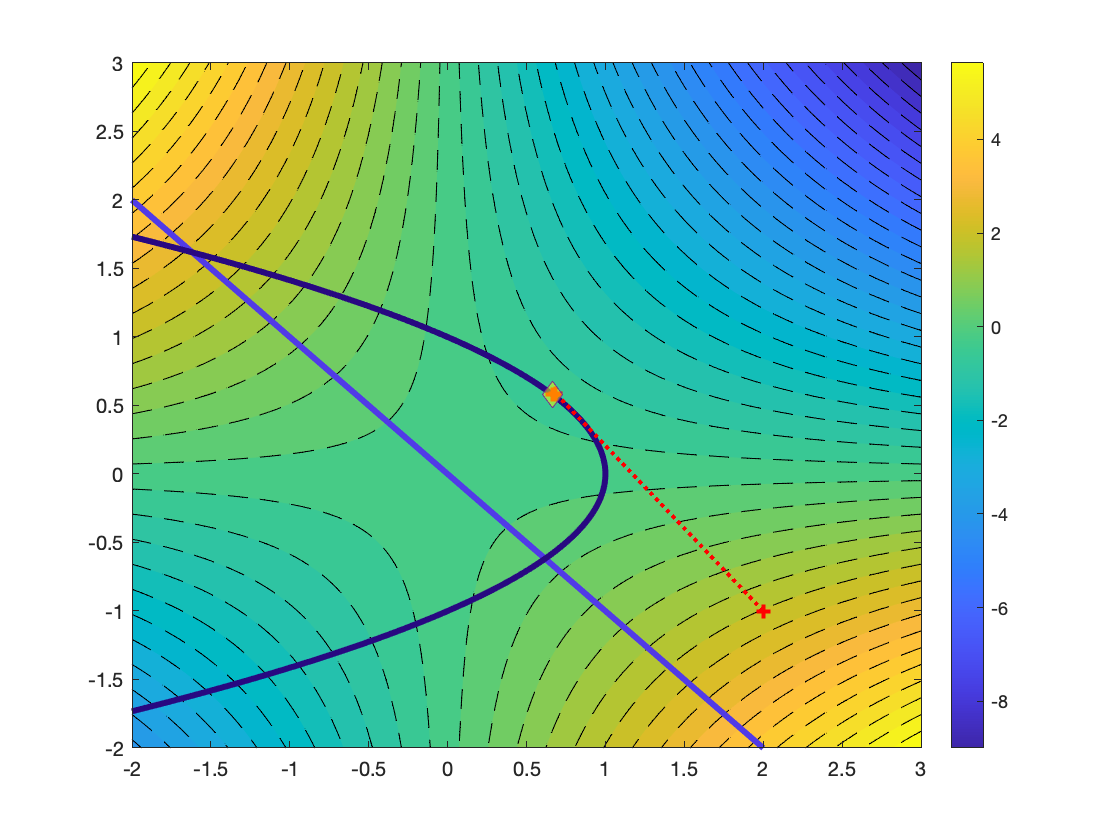

xx=-2:0.01:3;
yy=-2:0.01:3;
[X,Y]=meshgrid(xx,yy);
contourf(xx,yy,f0(X,Y),40,'--'); hold on; colorbar;
plot(xx,-xx,"LineWidth",3,"color",[81, 58, 232]/256);hold on;
plot(-yy.^2+1,yy,"LineWidth",3,"color",[40, 8, 130]/256);hold on;
plot(x(:,1),x(:,2) ,"r:","LineWidth",2,"Marker","+");hold on;
scatter(xhat(1),xhat(2),100,'d',"MarkerFaceColor","yellow","MarkerFaceAlpha",0.5); hold off;
xlim([-2,3]);ylim([-2,3]);

initial = [2,-1];
[x,xhat,fval]=penalty_barrier2d("barrier",f0,h1,h2,E,initial);

Initial point should be in feasible area to use barrier function


initial = [-0.5,1];
[x,xhat,fval]=penalty_barrier2d("penalty",f0,h1,h2,E,initial);
disp([num2str(xhat),'  fval:',num2str(fval)]);

0.66669     0.57736  fval:-0.38492


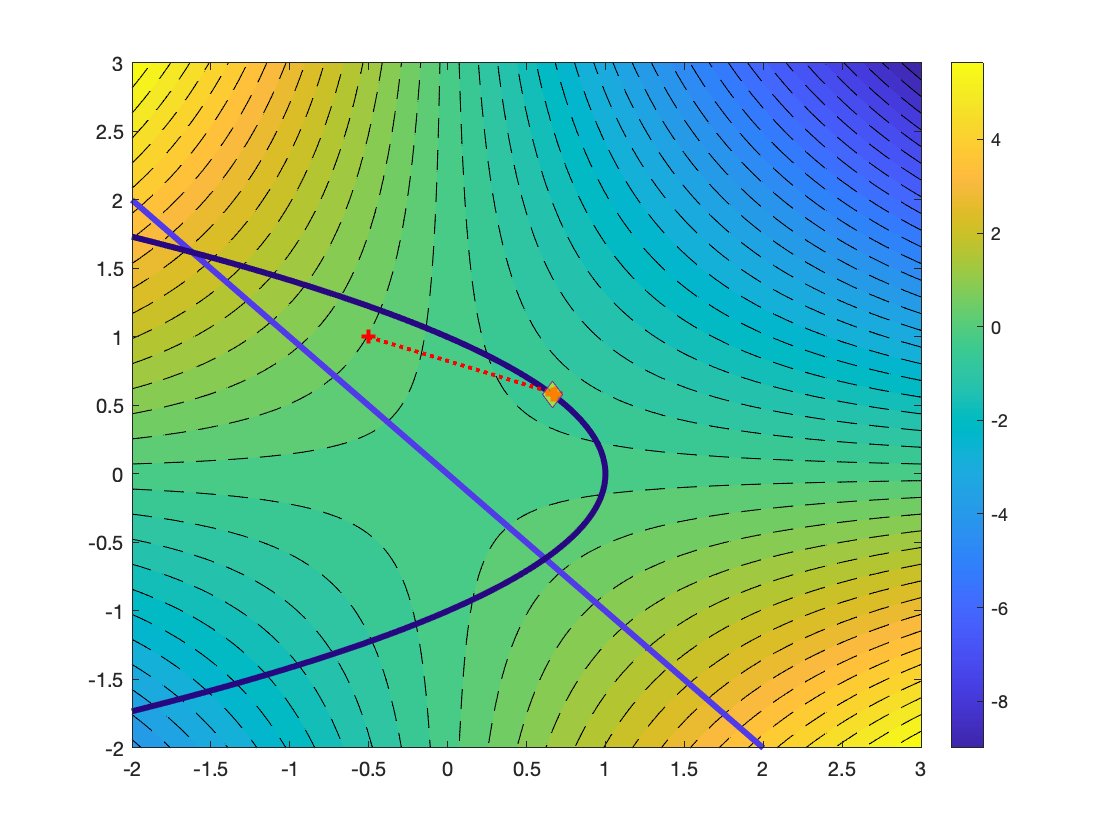

contourf(xx,yy,f0(X,Y),40,'--'); hold on; colorbar;
plot(xx,-xx,"LineWidth",3,"color",[81, 58, 232]/256);hold on;
plot(-yy.^2+1,yy,"LineWidth",3,"color",[40, 8, 130]/256);hold on;
plot(x(:,1),x(:,2) ,"r:","LineWidth",2,"Marker","+");hold on;
scatter(xhat(1),xhat(2),100,'d',"MarkerFaceColor","yellow","MarkerFaceAlpha",0.5); hold off;
xlim([-2,3]);ylim([-2,3]);

### (3) 1 Inequality, 1 equality constraint

minimize $V\left(x,y\right)=\ln \left(x\right)-y;\;$$x,y\in R$

subject to : $\begin{array}{l}
h_1 \left(x,y\right)=x-1\ge 0\;\\
\;h_2 \left(x,y\right)=x^2 +y^2 -4=0
\end{array}$

f0 = @(x,y) log(x)-y;
h1 = @(x,y) x-1; %>=0
h2 = @(x,y) x.^2+y.^2-4; %==0
initial = [3,3];
E=1;
[x,xhat,fval]=penalty_barrier2d("penalty",f0,h1,h2,E,initial);
disp([num2str(xhat),'  fval:',num2str(fval)]);

0.99992      1.7321  fval:-1.7322


Constraints are marked in dark blue, and background is a contour of objective function. A path that this algorithm searched for each iteration is marked in red. The final minimum estimation $\hat{x}$ is marked in yello diamond.

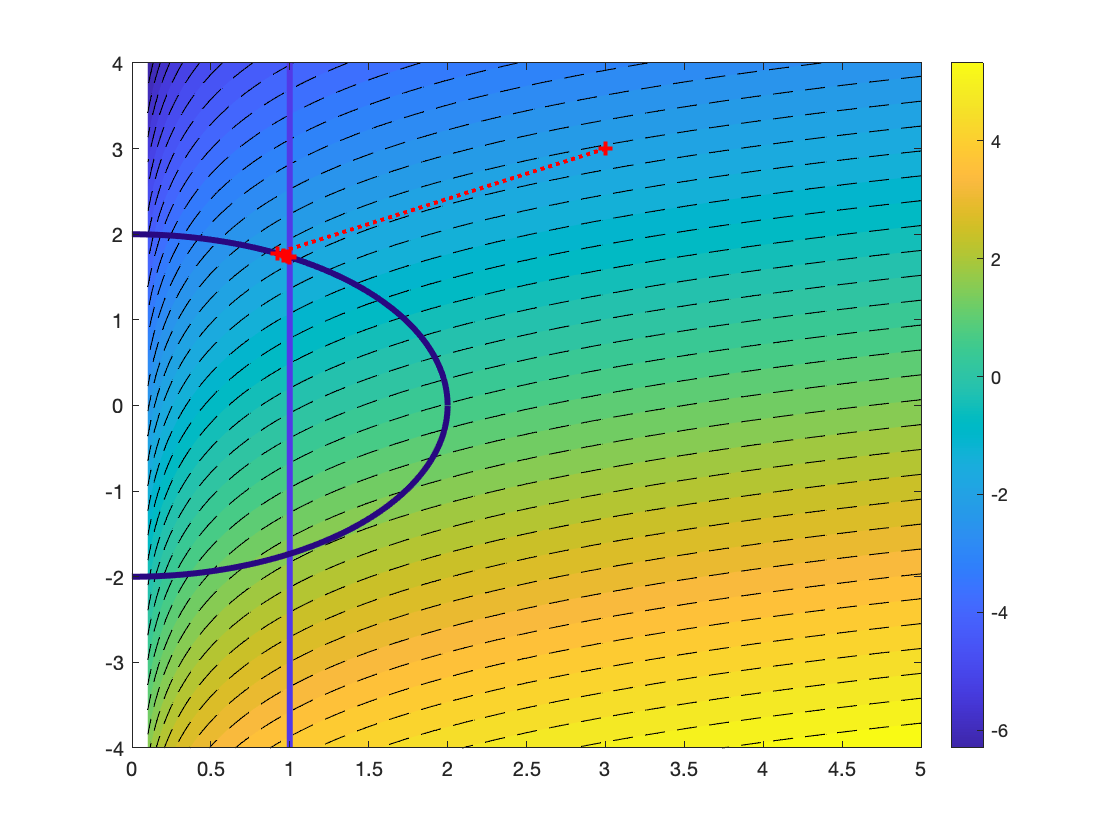

xx=0.1:0.01:5;
yy=-4:0.01:4;
[X,Y]=meshgrid(xx,yy);
contourf(xx,yy,f0(X,Y),40,'--'); hold on;  colorbar;
plot(ones(length(yy)),yy,"LineWidth",3,"color",[81, 58, 232]/256);hold on;
ang=0:0.01:2*pi; plot(2*cos(ang),2*sin(ang),"LineWidth",3,"color",[40, 8, 130]/256);hold on;
plot(x(:,1),x(:,2) ,"r:","LineWidth",2,"Marker","+");hold off;
xlim([0,5]);